Fs = 20;
trim = 5;

datasetname = ["Normal1"; "Normal2"; "Normal3"; "Normal4"; "Normal5"; "Cross1"; "Cross2"; "Cross3"; "Cross4"; "Cross5"; "InOut1"; "InOut2"; "InOut3"; "InOut4"; "InOut5"];
movename = strings([length(datasetname),1]);

for n=1:length(datasetname)
    [MotionDataNormal]=ParseMatlabApp('RohilTestData\' + datasetname(n));
    raw_t = MotionDataNormal.t_Accel;
    raw_accel = MotionDataNormal.Accel;
    
    [trimmed_time,trimmed_accel]=trim_time_data(raw_t,raw_accel,Fs,trim);
    averaged_accel=movingaverage(trimmed_accel);
    
    [averaged_freq,averaged_mag1]=get_freq_vars(averaged_accel(:,1),Fs);
    [averaged_freq,averaged_mag2]=get_freq_vars(averaged_accel(:,2),Fs);
    [averaged_freq,averaged_mag3]=get_freq_vars(averaged_accel(:,3),Fs);
    averaged_mag = zeros(length(averaged_mag1),3);
    averaged_mag(:,1)=averaged_mag1;
    averaged_mag(:,2)=averaged_mag2;
    averaged_mag(:,3)=averaged_mag3;
    filtered_mag=filter_lowpass(averaged_freq,averaged_mag,Fs);
    nongravity_mag=remove_gravity(averaged_freq,filtered_mag);
    
%     figure
%     subplot(3,2,1);
%     make_time_plot(raw_accel(:,1), Fs, 'ax')
%     subplot(3,2,2);
%     make_freq_plot(raw_accel(:,1), Fs, 'ax')
%     subplot(3,2,3);
%     make_time_plot(raw_accel(:,2), Fs, 'ay')
%     subplot(3,2,4);
%     make_freq_plot(raw_accel(:,2), Fs, 'ay')
%     subplot(3,2,5);
%     make_time_plot(raw_accel(:,3), Fs, 'az')
%     subplot(3,2,6);
%     make_freq_plot(raw_accel(:,3), Fs, 'az')
%     sgtitle('Raw Data')
%     
%     figure
%     subplot(3,2,1);
%     plot(trimmed_time,averaged_accel(:,1))
%     l = sprintf('Time (s).\n sample rate of %.2f Hz assumed.', Fs);
%     xlabel(l);
%     title('ax')
%     subplot(3,2,2);
%     plot(averaged_freq,nongravity_mag(:,1))
%     ylabel('Magnitude of FFT');
%     xlabel('Frequency (Hz)');
%     title('ax')
%     subplot(3,2,3);
%     plot(trimmed_time,averaged_accel(:,2))
%     l = sprintf('Time (s).\n sample rate of %.2f Hz assumed.', Fs);
%     xlabel(l);
%     title('ay')
%     subplot(3,2,4);
%     plot(averaged_freq,nongravity_mag(:,2))
%     ylabel('Magnitude of FFT');
%     xlabel('Frequency (Hz)');
%     title('ay')
%     subplot(3,2,5);
%     plot(trimmed_time,averaged_accel(:,3))
%     l = sprintf('Time (s).\n sample rate of %.2f Hz assumed.', Fs);
%     xlabel(l);
%     title('az')
%     subplot(3,2,6);
%     plot(averaged_freq,nongravity_mag(:,3))
%     ylabel('Magnitude of FFT');
%     xlabel('Frequency (Hz)');
%     title('az')
%     sgtitle('Processed Data')
    
    move_name=move_algorithm(averaged_freq,nongravity_mag);
    movename(n,1)=move_name;
end

disp("Rohil Move Identification")

Rohil Move Identification


disp("Should show five normal dribbles, five crossovers, and five in and outs")

Should show five normal dribbles, five crossovers, and five in and outs


movename

movename = 15×1 string array
    "Normal Dribble"
    "Normal Dribble"
    "Normal Dribble"
    "Normal Dribble"
    "Normal Dribble"
    "Crossover"
    "Crossover"
    "Crossover"
    "Crossover"
    "Crossover"
    "In And Out"
    "In And Out"
    "In And Out"
    "In And Out"
    "In And Out"


Fs = 20;
trim = 5;

datasetname = ["Normal1"; "Normal2"; "Normal3"; "Normal4"; "Normal5"; "Cross1"; "Cross2"; "Cross3"; "Cross4"; "Cross5"; "InOut1"; "InOut2"; "InOut3"; "InOut4"; "InOut5"];
movename = strings([length(datasetname),1]);

for n=1:length(datasetname)
    [MotionDataNormal]=ParseMatlabApp('EmilyMobileSensorData\' + datasetname(n));
    raw_t = MotionDataNormal.t_Accel;
    raw_accel = MotionDataNormal.Accel;
    
    [trimmed_time,trimmed_accel]=trim_time_data(raw_t,raw_accel,Fs,trim);
    averaged_accel=movingaverage(trimmed_accel);
    
    [averaged_freq,averaged_mag1]=get_freq_vars(averaged_accel(:,1),Fs);
    [averaged_freq,averaged_mag2]=get_freq_vars(averaged_accel(:,2),Fs);
    [averaged_freq,averaged_mag3]=get_freq_vars(averaged_accel(:,3),Fs);
    averaged_mag = zeros(length(averaged_mag1),3);
    averaged_mag(:,1)=averaged_mag1;
    averaged_mag(:,2)=averaged_mag2;
    averaged_mag(:,3)=averaged_mag3;
    filtered_mag=filter_lowpass(averaged_freq,averaged_mag,Fs);
    nongravity_mag=remove_gravity(averaged_freq,filtered_mag);
    
%     figure
%     subplot(3,2,1);
%     make_time_plot(raw_accel(:,1), Fs, 'ax')
%     subplot(3,2,2);
%     make_freq_plot(raw_accel(:,1), Fs, 'ax')
%     subplot(3,2,3);
%     make_time_plot(raw_accel(:,2), Fs, 'ay')
%     subplot(3,2,4);
%     make_freq_plot(raw_accel(:,2), Fs, 'ay')
%     subplot(3,2,5);
%     make_time_plot(raw_accel(:,3), Fs, 'az')
%     subplot(3,2,6);
%     make_freq_plot(raw_accel(:,3), Fs, 'az')
%     sgtitle('Raw Data')
%     
%     figure
%     subplot(3,2,1);
%     plot(trimmed_time,averaged_accel(:,1))
%     l = sprintf('Time (s).\n sample rate of %.2f Hz assumed.', Fs);
%     xlabel(l);
%     title('ax')
%     subplot(3,2,2);
%     plot(averaged_freq,nongravity_mag(:,1))
%     ylabel('Magnitude of FFT');
%     xlabel('Frequency (Hz)');
%     title('ax')
%     subplot(3,2,3);
%     plot(trimmed_time,averaged_accel(:,2))
%     l = sprintf('Time (s).\n sample rate of %.2f Hz assumed.', Fs);
%     xlabel(l);
%     title('ay')
%     subplot(3,2,4);
%     plot(averaged_freq,nongravity_mag(:,2))
%     ylabel('Magnitude of FFT');
%     xlabel('Frequency (Hz)');
%     title('ay')
%     subplot(3,2,5);
%     plot(trimmed_time,averaged_accel(:,3))
%     l = sprintf('Time (s).\n sample rate of %.2f Hz assumed.', Fs);
%     xlabel(l);
%     title('az')
%     subplot(3,2,6);
%     plot(averaged_freq,nongravity_mag(:,3))
%     ylabel('Magnitude of FFT');
%     xlabel('Frequency (Hz)');
%     title('az')
%     sgtitle('Processed Data')
    
    move_name=move_algorithm(averaged_freq,nongravity_mag);
    movename(n,1)=move_name;
end

disp("Emily Move Identification")

Emily Move Identification


disp("Should show five normal dribbles, five crossovers, and five in and outs")

Should show five normal dribbles, five crossovers, and five in and outs


movename

movename = 15×1 string array
    "Normal Dribble"
    "Normal Dribble"
    "Normal Dribble"
    "Normal Dribble"
    "Normal Dribble"
    "Crossover"
    "Crossover"
    "Crossover"
    "Crossover"
    "Crossover"
    "Crossover"
    "Crossover"
    "Crossover"
    "Crossover"
    "Crossover"


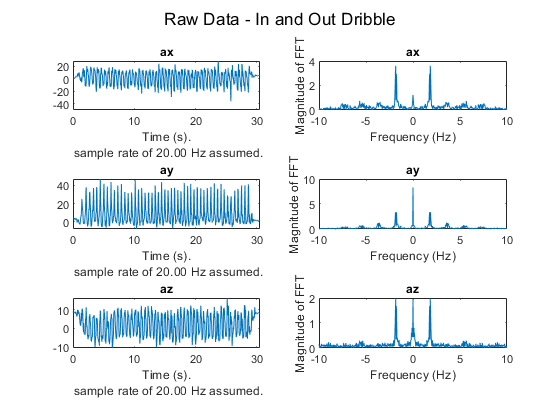

[MotionDataNormal]=ParseMatlabApp('InitialData\Inandout');
raw_t = MotionDataNormal.t_Accel;
raw_accel = MotionDataNormal.Accel;

[trimmed_time,trimmed_accel]=trim_time_data(raw_t,raw_accel,Fs,trim);
averaged_accel=movingaverage(trimmed_accel);

[averaged_freq,averaged_mag1]=get_freq_vars(averaged_accel(:,1),Fs);
[averaged_freq,averaged_mag2]=get_freq_vars(averaged_accel(:,2),Fs);
[averaged_freq,averaged_mag3]=get_freq_vars(averaged_accel(:,3),Fs);
averaged_mag = zeros(length(averaged_mag1),3);
averaged_mag(:,1)=averaged_mag1;
averaged_mag(:,2)=averaged_mag2;
averaged_mag(:,3)=averaged_mag3;
filtered_mag=filter_lowpass(averaged_freq,averaged_mag,Fs);
nongravity_mag=remove_gravity(averaged_freq,filtered_mag);

figure
subplot(3,2,1);
make_time_plot(raw_accel(:,1), Fs, 'ax')
subplot(3,2,2);
make_freq_plot(raw_accel(:,1), Fs, 'ax')
subplot(3,2,3);
make_time_plot(raw_accel(:,2), Fs, 'ay')
subplot(3,2,4);
make_freq_plot(raw_accel(:,2), Fs, 'ay')
subplot(3,2,5);
make_time_plot(raw_accel(:,3), Fs, 'az')
subplot(3,2,6);
make_freq_plot(raw_accel(:,3), Fs, 'az')
sgtitle('Raw Data - In and Out Dribble')

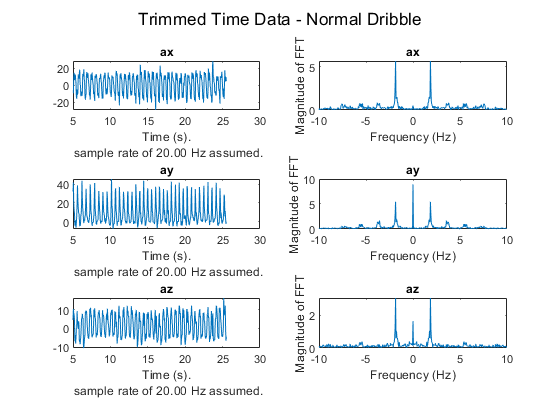


figure
subplot(3,2,1);
plot(trimmed_time,trimmed_accel(:,1))
l = sprintf('Time (s).\n sample rate of %.2f Hz assumed.', Fs);
xlabel(l);
title('ax')
subplot(3,2,2);
make_freq_plot(trimmed_accel(:,1), Fs, 'ax')
subplot(3,2,3);
plot(trimmed_time,trimmed_accel(:,2))
l = sprintf('Time (s).\n sample rate of %.2f Hz assumed.', Fs);
xlabel(l);
title('ay')
subplot(3,2,4);
make_freq_plot(trimmed_accel(:,2), Fs, 'ay')
subplot(3,2,5);
plot(trimmed_time,trimmed_accel(:,3))
l = sprintf('Time (s).\n sample rate of %.2f Hz assumed.', Fs);
xlabel(l);
title('az')
subplot(3,2,6);
make_freq_plot(trimmed_accel(:,3), Fs, 'az')
sgtitle('Trimmed Time Data - Normal Dribble')

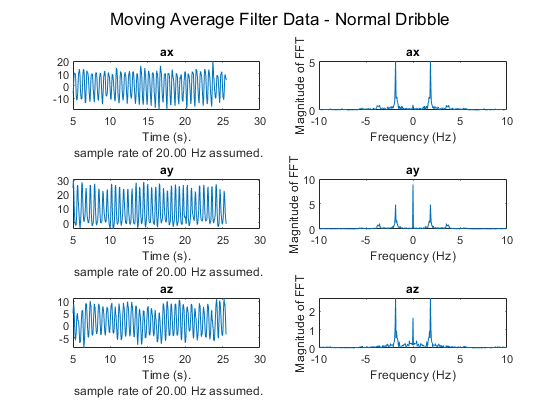


figure
subplot(3,2,1);
plot(trimmed_time,averaged_accel(:,1))
l = sprintf('Time (s).\n sample rate of %.2f Hz assumed.', Fs);
xlabel(l);
title('ax')
subplot(3,2,2);
make_freq_plot(averaged_accel(:,1), Fs, 'ax')
subplot(3,2,3);
plot(trimmed_time,averaged_accel(:,2))
l = sprintf('Time (s).\n sample rate of %.2f Hz assumed.', Fs);
xlabel(l);
title('ay')
subplot(3,2,4);
make_freq_plot(averaged_accel(:,2), Fs, 'ay')
subplot(3,2,5);
plot(trimmed_time,averaged_accel(:,3))
l = sprintf('Time (s).\n sample rate of %.2f Hz assumed.', Fs);
xlabel(l);
title('az')
subplot(3,2,6);
make_freq_plot(averaged_accel(:,3), Fs, 'az')
sgtitle('Moving Average Filter Data - Normal Dribble')

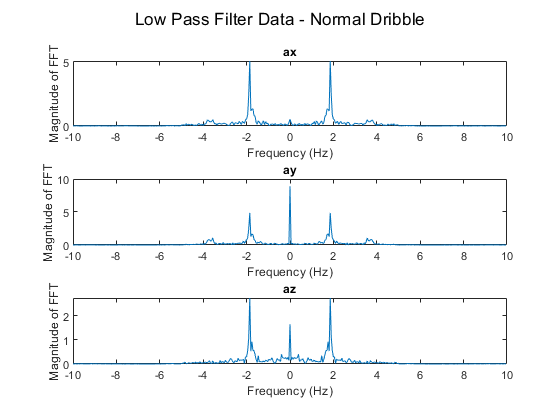


figure
% subplot(3,1,1);
% plot(trimmed_time,averaged_accel(:,1))
% l = sprintf('Time (s).\n sample rate of %.2f Hz assumed.', Fs);
% xlabel(l);
% title('ax')
subplot(3,1,1);
plot(averaged_freq,filtered_mag(:,1))
ylabel('Magnitude of FFT');
xlabel('Frequency (Hz)');
title('ax')
% subplot(3,1,2);
% plot(trimmed_time,averaged_accel(:,2))
% l = sprintf('Time (s).\n sample rate of %.2f Hz assumed.', Fs);
% xlabel(l);
% title('ay')
subplot(3,1,2);
plot(averaged_freq,filtered_mag(:,2))
ylabel('Magnitude of FFT');
xlabel('Frequency (Hz)');
title('ay')
% subplot(3,1,5);
% plot(trimmed_time,averaged_accel(:,3))
% l = sprintf('Time (s).\n sample rate of %.2f Hz assumed.', Fs);
% xlabel(l);
% title('az')
subplot(3,1,3);
plot(averaged_freq,filtered_mag(:,3))
ylabel('Magnitude of FFT');
xlabel('Frequency (Hz)');
title('az')
sgtitle('Low Pass Filter Data - Normal Dribble')

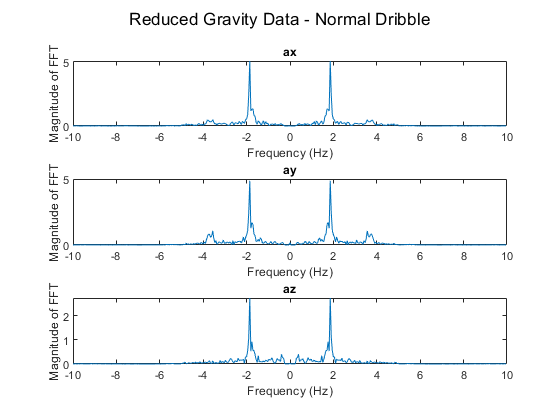


figure
% subplot(3,1,1);
% plot(trimmed_time,averaged_accel(:,1))
% l = sprintf('Time (s).\n sample rate of %.2f Hz assumed.', Fs);
% xlabel(l);
% title('ax')
subplot(3,1,1);
plot(averaged_freq,nongravity_mag(:,1))
ylabel('Magnitude of FFT');
xlabel('Frequency (Hz)');
title('ax')
% subplot(3,1,2);
% plot(trimmed_time,averaged_accel(:,2))
% l = sprintf('Time (s).\n sample rate of %.2f Hz assumed.', Fs);
% xlabel(l);
% title('ay')
subplot(3,1,2);
plot(averaged_freq,nongravity_mag(:,2))
ylabel('Magnitude of FFT');
xlabel('Frequency (Hz)');
title('ay')
% subplot(3,1,5);
% plot(trimmed_time,averaged_accel(:,3))
% l = sprintf('Time (s).\n sample rate of %.2f Hz assumed.', Fs);
% xlabel(l);
% title('az')
subplot(3,1,3);
plot(averaged_freq,nongravity_mag(:,3))
ylabel('Magnitude of FFT');
xlabel('Frequency (Hz)');
title('az')
sgtitle('Reduced Gravity Data - Normal Dribble')

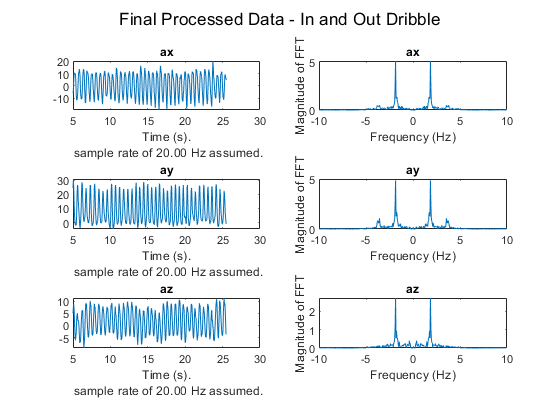


figure
subplot(3,2,1);
plot(trimmed_time,averaged_accel(:,1))
l = sprintf('Time (s).\n sample rate of %.2f Hz assumed.', Fs);
xlabel(l);
title('ax')
subplot(3,2,2);
plot(averaged_freq,nongravity_mag(:,1))
ylabel('Magnitude of FFT');
xlabel('Frequency (Hz)');
title('ax')
subplot(3,2,3);
plot(trimmed_time,averaged_accel(:,2))
l = sprintf('Time (s).\n sample rate of %.2f Hz assumed.', Fs);
xlabel(l);
title('ay')
subplot(3,2,4);
plot(averaged_freq,nongravity_mag(:,2))
ylabel('Magnitude of FFT');
xlabel('Frequency (Hz)');
title('ay')
subplot(3,2,5);
plot(trimmed_time,averaged_accel(:,3))
l = sprintf('Time (s).\n sample rate of %.2f Hz assumed.', Fs);
xlabel(l);
title('az')
subplot(3,2,6);
plot(averaged_freq,nongravity_mag(:,3))
ylabel('Magnitude of FFT');
xlabel('Frequency (Hz)');
title('az')
sgtitle('Final Processed Data - In and Out Dribble')


move_name=move_algorithm(averaged_freq,nongravity_mag);
movename(n,1)=move_name;